# Atividade 10

## Resposta em Frequencia 

### Modelagem

A fim de de analisarmos a resposta em frequencia do sistema em questao, precisamos primeiro termos um modelo. 

Como estamos lidando com um sistema de 1 grau de liberdade (1DOF), i.e um sitema que com somente uma cordenada somos capazes de descrever totalmente seu estado cinematico, iremos utilizar o seguinte modelo:


$$\ddot x + 2\zeta \omega_n \dot x + \omega_n^2 x = a(t); \ \ \ 
\begin{cases}

\zeta = c/(2m\omega_n) \\ 
\omega_n = \sqrt{k/m}

\end{cases}$$


Onde:

- $\zeta \rightarrow$ Representa o Coeficiente de Amortecimento viscoso.

- $\omega_n \rightarrow$Rrepresenta a frequencia natural de vibracao do sistema.

### Identificacao de Sistema

Como temos agora o modelo, podemos analisar a resposta em frequencia obtida pelo nosso sistema, a fim de identificarmos os valores de cada componente do nosso modelo.

#### Frequencia Natural ($\omega_n$)

O primeiro que somos capazes de encontrar e a frequencia natural, pois e a frequencia na qual ocorre um shift de $90^\circ$ na fase, que para o nosso sistema eh dado por:


$$\omega_n \approx 4.5 \times 10^3 rad/s$$


#### Constante Elastica ($k$)

O segundo parametro que somos capazes de identificar, a partir diretamenta da frequencia natural acima, eh a constante elastica, tendo em vista a seguinte relacao:


$$\omega_n = \sqrt{k/m} \ \ \therefore \ \  k = m\omega_n^2$$


omega_pico = 4e3;
omega_n = 4.5e3;
m = 20e-3;

k = m * omega_n^2

k = 405000

#### Coeficiente de Amortecimento  ($\zeta$)

Outro parametro que somos capazes de determinar a partir do grafico e da frequencia natural eh o coeficiente de amortecimento. Para o modelo usado, a funcao de resposta em frequencia resulta em um fator de amplificacao $MF$ dado por:


$$MF = \frac{1}{\sqrt{(1 - r^2)^2+(2\zeta r)^2}}; \ \ \ r = \Omega / \omega_n$$


Pelo qual somos capazes de determinar $\zeta$ a partir do pico de resposta em frequencia $MF_{pico
}$ representado pelo maior valor no grafico de magnitude e a sua frequencia de ocorrencia $\Omega_{pico}$. Para tal caso temos que $MF_{max}$ e $r_{pico}$ sao modelados por:


$$MF_{pico} = \frac{1}{2\zeta\sqrt{1 - \zeta^2}}; \ \ r_{pico} = \sqrt{1 - 2\zeta^2}$$


Como sabemos o valor da frequencia natural, a frequencia de pico temos $r_{pico}$ e, por conseguinte, o valor de $\zeta$:


$$r_{pico} = \frac{\Omega}{\omega_n} = \sqrt{1 - 2\zeta^2} \therefore \zeta = \sqrt{\frac{1}{2}\left[1 - \left(\frac{\Omega}{\omega_n}\right)^2\right]}$$


zeta = sqrt((1/2) * (1 - (omega_pico/omega_n)^2))

zeta = 0.3239

#### Constante de Amortecimento ($c$)

E a partir do coeficiente de amortecimento, massa e frequencia natural somos capazes de determinar a constante de amortecimento $c$, pela seguinte equacao:


$$\zeta = c/(2m\omega_n) \therefore c = \zeta(2m\omega_n)$$


c = zeta * (2 * m * omega_n)

c = 58.3095

### Funcao de Transferencia

Como podemos observar tanto pelo modelo matematico desenvolvido anteiormente quanto pela resposta em frequencia (bode plot) temos que o sistema eh de segunda ordem. Com isso, temos que sua funcao de transferencia eh dada por:


$$G(s) = \frac{K\omega_n^2}{s^2 + 2\zeta\omega_ns + \omega_n^2}; \ \ K = 10^{M(0)/20}$$


Onde $K$ representa o ganho DC que o sistema tem em relacao a entrada de excitacao, em funcao de $M(0)$, que representa o ganho para entrada com frequencia nula ( $\Omega = 0 rad/s$).

K = 10^(-40/20)

K = 0.0100

Podemos averiguar que nossa modelagem esta coerente ao fazermos o bode plot:

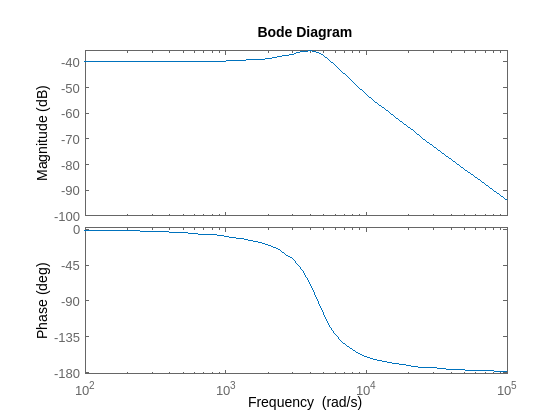

transfer_f = tf(K*omega_n^2, [1 2*omega_n*zeta omega_n^2]);
bode(transfer_f)

## Resposta em Degrau

A partir do modelo acima, podemos tambem modelar a resposta do nosso sistema para uma excitacao de degrau unitario (tambem chamada de Heaviside).  Para isso, poderiamos utilizar a definicao da funcao de transferencia e de Heaviside, e entao fazer a laplace inversa, ou podemos utilizar o comando do matlab $step$:

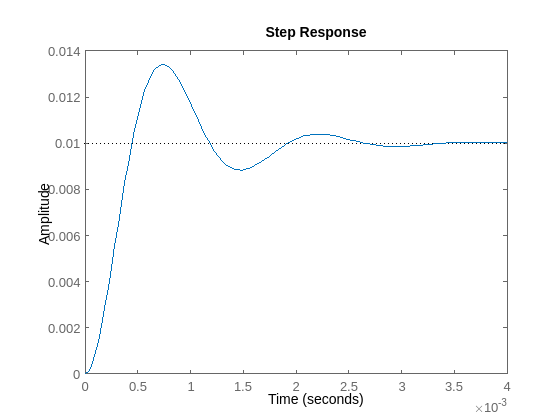

step(transfer_f)

## Entrada Arbitraria e Perfis Cinematicos

O sistema de aquisicao de dados possui uma frequencia de sampling $F_{s}=1KHz$, e um transdutor com um ganho de $K_{gain} = 200 V/m$. A partir desses parametros, e dos dados coletados, temos o seguinte perfil de deslocamento:

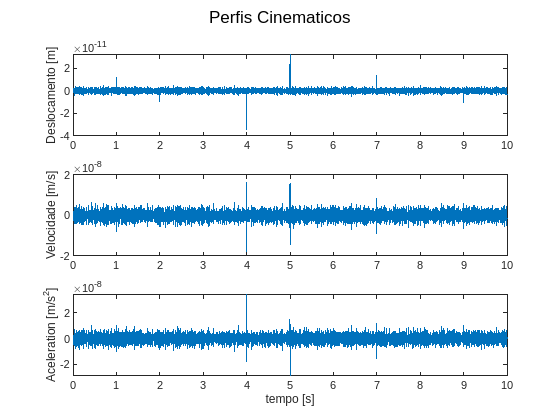

raw_data = readtable("data/Data10.csv");
raw_data.Properties.VariableNames = {'Voltage'};

Fs = 1e3;
K_gain = 200;
Ts = 1/Fs;

raw_data.Voltage = 1e-3 .* raw_data.Voltage;
raw_data.Deslocamento = raw_data.Voltage ./ K_gain;
raw_data.Velocidade   = [0; diff(raw_data.Deslocamento, 1) / Ts];
raw_data.Aceleracao   = [0; 0; diff(raw_data.Deslocamento, 2) / Ts];

time = 0:Ts:(length(raw_data.Voltage) * Ts);
time = time(1 : end-1);

subplot(3, 1, 1);
plot(time', raw_data.Deslocamento);
ylabel('Deslocamento [m]');

subplot(3, 1, 2);
plot(time, raw_data.Velocidade);
ylabel('Velocidade [m/s]');

subplot(3, 1, 3);
plot(time, raw_data.Aceleracao);
ylabel('Aceleration [m/s^2]');
xlabel('tempo [s]');
sgtitle('Perfis Cinematicos');